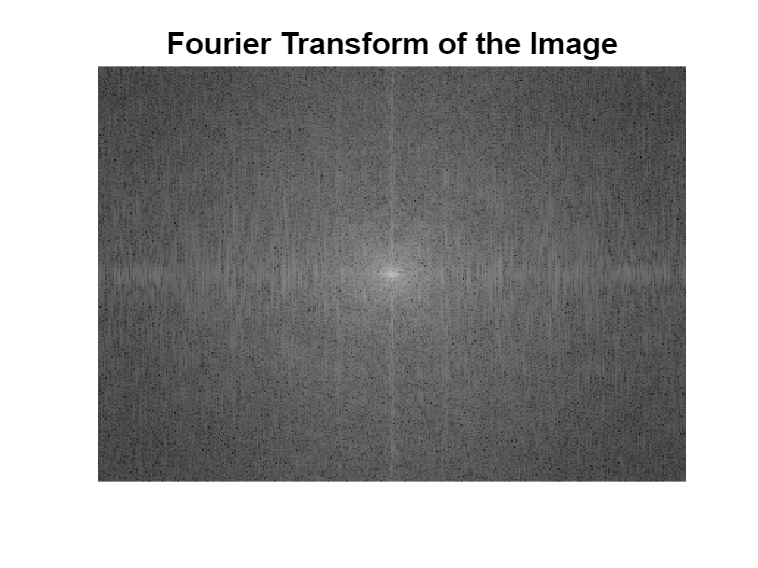

% Load the input image and convert to grayscale
input_image = imread('https://st4.depositphotos.com/6903990/27898/i/1600/depositphotos_278981062-stock-photo-beautiful-young-woman-clean-fresh.jpg');  % Replace 'image.jpg' with your image path
grayscale_image = rgb2gray(input_image);  % Convert the image to grayscale

% Perform 2D Fast Fourier Transform (FFT)
fft_image = fft2(double(grayscale_image));  % Compute the 2D FFT of the grayscale image
fft_shifted_image = fftshift(fft_image);    % Shift the zero-frequency component to the center of the spectrum

% Display the Fourier Transform result (logarithmic scale for better visibility)
figure;
imshow(log(1 + abs(fft_shifted_image)), []);  % Visualize the Fourier transform
title('Fourier Transform of the Image');

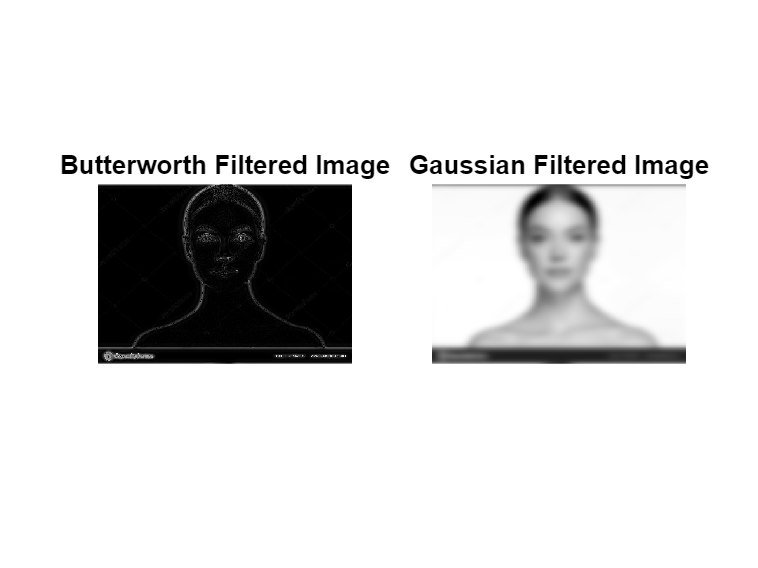


% Parameters for the Butterworth and Gaussian filters
cutoff_frequency = 30;  % Cutoff frequency for Butterworth filter
[image_height, image_width] = size(grayscale_image);  % Get image dimensions

% Create frequency domain meshgrid (centered at zero)
[x, y] = meshgrid(-image_width/2:image_width/2-1, -image_height/2:image_height/2-1);
distance_matrix = sqrt(x.^2 + y.^2);  % Distance from the origin in frequency domain

% Apply Butterworth Filter (Low-Pass Filter)
butterworth_order = 2;  % Order of the Butterworth filter
butterworth_filter = 1 ./ (1 + (cutoff_frequency ./ distance_matrix).^(2 * butterworth_order));

% Apply Butterworth filter in frequency domain and inverse FFT to get the filtered image
butterworth_filtered_image = ifft2(fft_shifted_image .* butterworth_filter);
butterworth_filtered_image = abs(butterworth_filtered_image);  % Take the magnitude of the result

% Parameters for Gaussian Filter
gaussian_sigma = 10;  % Standard deviation for Gaussian filter

% Create Gaussian filter in frequency domain
gaussian_filter = exp(-(distance_matrix.^2) / (2 * gaussian_sigma^2));

% Apply Gaussian filter in frequency domain and inverse FFT to get the filtered image
gaussian_filtered_image = ifft2(fft_shifted_image .* gaussian_filter);
gaussian_filtered_image = abs(gaussian_filtered_image);  % Take the magnitude of the result

% Display the Butterworth and Gaussian filtered images
figure;
subplot(1, 2, 1); imshow(butterworth_filtered_image, []); title('Butterworth Filtered Image');
subplot(1, 2, 2); imshow(gaussian_filtered_image, []); title('Gaussian Filtered Image');